clear; close all; rng(1);


## Setup

% Number Samples
N = 50;
% Generate Reference
[b,a]  = butter(8, 0.1);
ur     = filtfilt(b, a, 0.5*randn(N,1));
c_func = @(n, x)feedforward_control_function(n, x, ur);
r      = run_single_pendulum_fffb_dynamics(c_func, N);

% Initial Input Trajectory
u = 0.1*randn(N,1);
% Number of trials
J = 30;
% Output matrix
C = [1, 0];
% Number inputs
R = 1;
% Number states
M = 2;

% Setup FFFB-Mole Object
fffb_mole = CFFFBMOLE(@run_single_pendulum_fffb_dynamics, R, M, C);


% Run FFFB-MOLE
tic; 
[ev1, ec1, yc1, uc1] = fffb_mole.run_fffb_mole(r, u, J);
toc;

Elapsed time is 15.985841 seconds.



% Run AI-MOLE for comparison
tic; 
[ev2, ec2, yc2, uc2] = fffb_mole.run_vanilla_mole(r, u, J);
toc;

Elapsed time is 10.217661 seconds.


## Plot Results

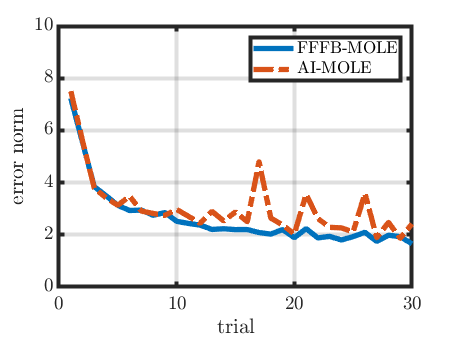

% Plot error norms over trials
figure; 
plot(ev1); hold on;
plot(ev2, '-.');
xlim([0, J]);
ylim([0, 10]);
legend('FFFB-MOLE', 'AI-MOLE');
xlabel('trial');
ylabel('error norm');